# Machine Learning: Programming Exercise 2 

## Logistic Regression

In this exercise, you will implement logistic regression and apply it to two different datasets.

### Files needed for this exercise

- `ex2.mlx` - MATLAB Live Script that steps you through the exercise

- ex2data1.txt - Training set for the first half of the exercise

- ex2data2.txt - Training set for the second half of the exercise

- `submit.m` - Submission script that sends your solutions to our servers

- `mapFeature.m` - Function to generate polynomial features

- `plotDecisionBoundary.m` - Function to plot classifier's decision boundary

- *`plotData.m` - Function to plot 2D classification data

- *`sigmoid.m` - Sigmoid function

- *`costFunction.m` - Logistic regression cost function

- *`predict.m` - Logistic regression prediction function

- `*costFunctionReg.m` - Regularized logistic regression cost function

****indicates files you will need to complete***

#### Confirm that your Current Folder is set correctly

Click into this section, then click the 'Run section' button above. This will execute the `dir` command below to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex2' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

dir

### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README` and have checked for an existing solution before seeking help on the discussion forums.

## 1. Logistic Regression

In this part of the exercise, you will build a logistic regression model to predict whether a student gets admitted into a university. Suppose that you are the administrator of a university department and you want to determine each applicant's chance of admission based on their results on two exams. You have historical data from previous applicants that you can use as a training set for logistic regression. For each training example, you have the applicant's scores on two exams and the admissions decision.

    Your task is to build a classification model that estimates an applicant's probability of admission based the scores from those two exams. `ex2.mlx` will guide you through the exercise. To begin, run the code below to load the data into MATLAB.

% Load Data
% The first two columns contain the exam scores and the third column contains the label.
data = load('ex2data1.txt');
X = data(:, [1, 2]); y = data(:, 3);

### 1.1 Visualizing the data

Before starting to implement any learning algorithm, it is always good to visualize the data if possible. The code below will load the data and display it on a 2-dimensional plot by calling the function `plotData`. You will now complete the code in `plotData` so that it displays a figure like Figure 1, where the axes are the two exam scores, and the positive and negative examples are shown with different markers.

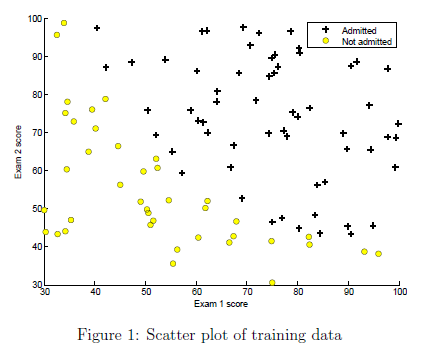

To help you get more familiar with plotting, we have left `plotData.m` empty so you can try to implement it yourself. However, this is an optional (ungraded) exercise. We also provide our implementation below so you can copy it or refer to it. If you choose to copy our example, make sure you learn what each of its commands is doing by consulting the MATLAB documentation.

Once you have added your own or the above code to `plotData.m`, run the code in this section to call the `plotData` function.

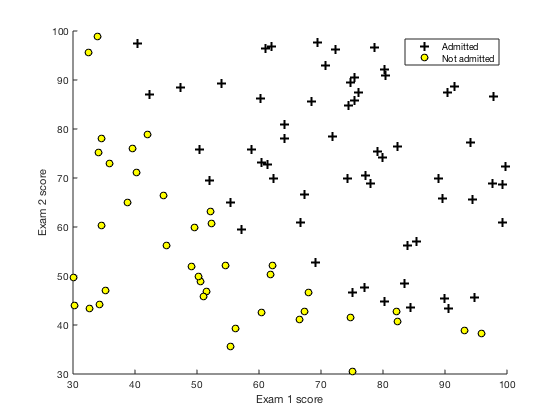

% Plot the data with + indicating (y = 1) examples and o indicating (y = 0) examples.
plotData(X, y);
 
% Labels and Legend
xlabel('Exam 1 score')
ylabel('Exam 2 score')

% Specified in plot order
legend('Admitted', 'Not admitted')

### 1.2 Implementation

#### 1.2.1 Warmup exercise: sigmoid function

Before you start with the actual cost function, recall that the logistic regression hypothesis is defined as:


$$ h_{\theta}(x) = g(\theta^Tx),$$


where function $g$ is the sigmoid function. The sigmoid function is defined as:


$$g(z) = \frac{1}{1+e^{-z}}$$


    Your first step is to implement this function in `sigmoid.m` so it can be called by the rest of your program. When you are finished, try testing a few values by calling `sigmoid(x)` in the code section below. For large positive values of `x`, the sigmoid should be close to 1, while for large negative values, the sigmoid should be close to 0. Evaluating `sigmoid(0)` should give you exactly 0.5. **Your code should also work with vectors and matrices**. For a matrix, your function should perform the sigmoid function on every element.

% Provide input values to the sigmoid function below and run to check your implementation
sigmoid(0)

ans = 0.5000

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

#### 1.2.2 Cost function and gradient

Now you will implement the cost function and gradient for logistic regression. Complete the code in `costFunction.m` to return the cost and gradient. Recall that the cost function in logistic regression is


$$J(\theta) =\frac{1}{m}\sum_{i=1}^m{\left[

-y^{(i)} \log(h_{\theta}(x^{(i)}))- (1 -y^{(i)}) \log(1- h_{\theta}(x^{(i)}))\right],$$


and the gradient of the cost is a vector of the same length as $\theta$ where the $j$th element (for $j = 0,\; 1,\ldots, n)$ is defined as follows:


$$\frac{\partial J(\theta)}{\partial \theta_j} = \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}$$


Note that while this gradient looks identical to the linear regression gradient, the formula is actually different because linear and logistic regression have different definitions of $h_{\theta}(x)$. Once you are done, run the code sections below to set up your data and call your `costFunction` using the initial parameters of $\theta$. You should see that the cost is about 0.693 and gradients of about -0.1000,  -12.0092, and -11.2628

%  Setup the data matrix appropriately

[m, n] = size(X);

% Add intercept term to X
X = [ones(m, 1) X];
% Initialize the fitting parameters
initial_theta = zeros(n + 1, 1);

% Compute and display the initial cost and gradient
[cost, grad] = costFunction(initial_theta, X, y);
fprintf('Cost at initial theta (zeros): %f\n', cost);

Cost at initial theta (zeros): 0.693147


disp('Gradient at initial theta (zeros):'); disp(grad);

Gradient at initial theta (zeros):
   -0.1000
  -12.0092
  -11.2628



#### 1.2.3 Learning parameters using `fminunc`

In the previous assignment, you found the optimal parameters of a linear regression model by implementing gradent descent. You wrote a cost function and calculated its gradient, then took a gradient descent step accordingly. This time, instead of taking gradient descent steps, you will use a MATLAB built-in function called `fminunc`. 

    MATLAB's `fminunc` is an optimization solver that finds the minimum of an unconstrained* function. For logistic regression, you want to optimize the cost function $J(\theta)$ with parameters. Concretely, you are going to use `fminunc` to find the best parameters $\theta$ for the logistic regression cost function, given a fixed dataset (of $X$ and $y$ values). You will pass to `fminunc` the following inputs:

- The initial values of the parameters we are trying to optimize.

- A function that, when given the training set and a particular $\theta$ computes the logistic regression cost and gradient with respect to $\theta$ for the dataset $(X, y)$

**Constraints in optimization often refer to constraints on the parameters, for example, constraints that bound the possible values *$\theta$* can take (e.g. *$\theta<1$*). Logistic regression does not have such constraints since *$\theta$* is allowed to take any real value.*

We already have code written below to call `fminunc` with the correct arguments:

- We first define the options to be used with `fminunc`. Specically, we set the `GradObj` option to `on`, which tells `fminunc` that our function returns both the cost and the gradient. This allows `fminunc` to use the gradient when minimizing the function. 

- Furthermore, we set the `MaxIter` option to 400, so that `fminunc` will run for at most 400 steps before it terminates. 

- To specify the actual function we are minimizing, we use a 'short-hand' for specifying functions with: `@(t)(costFunction(t,X,y))`. This creates a function, with argument `t`, which calls your `costFunction`. This allows us to wrap the `costFunction` for use with `fminunc`.

- If you have completed the `costFunction` correctly, `fminunc` will converge on the right optimization parameters and return the final values of the cost and $\theta$. Notice that by using `fminunc`, you did not have to write any loops yourself, or set a learning rate like you did for gradient descent. This is all done by `fminunc`: you only needed to provide a function calculating the cost and the gradient.

- Once `fminunc` completes, the remaining code will call your `costFunction` function using the optimal parameters of $\theta$. You should see that the cost is about 0.203. This final $\theta$ value will then be used to plot the decision boundary on the training data, resulting in a figure similar to Figure 2. We also encourage you to look at the code in `plotDecisionBoundary.m` to see how to plot such a boundary using the $\theta$ values.

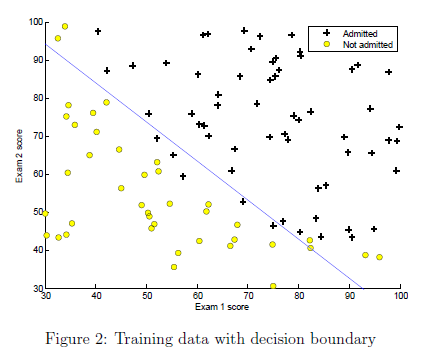

Run the code below and verify the results.

%  Set options for fminunc
options = optimoptions(@fminunc,'Algorithm','Quasi-Newton','GradObj', 'on', 'MaxIter', 400);

%  Run fminunc to obtain the optimal theta
%  This function will return theta and the cost 
[theta, cost] = fminunc(@(t)(costFunction(t, X, y)), initial_theta, options);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



% Print theta
fprintf('Cost at theta found by fminunc: %f\n', cost);

Cost at theta found by fminunc: 0.203498


disp('theta:');disp(theta);

theta:
  -25.1613
    0.2062
    0.2015



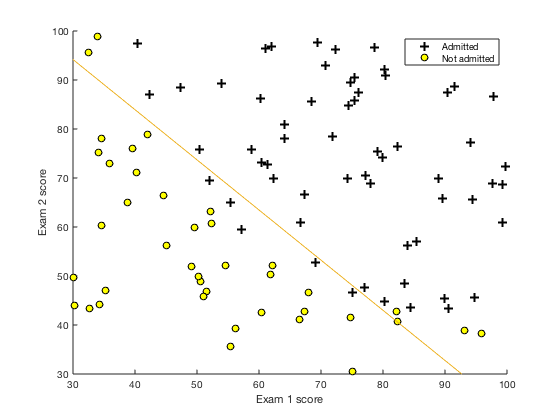


% Plot Boundary
plotDecisionBoundary(theta, X, y);
% Add some labels 
hold on;
% Labels and Legend
xlabel('Exam 1 score')
ylabel('Exam 2 score')
% Specified in plot order
legend('Admitted', 'Not admitted')
hold off;

#### 1.2.4 Evaluating logistic regression

After learning the parameters, you can use the model to predict whether a particular student will be admitted. For a student with an Exam 1 score of 45 and an Exam 2 score of 85, you should expect to see an admission probability of 0.776. Another way to evaluate the quality of the parameters we have found is to see how well the learned model predicts on our training set. In this part, your task is to complete the code in `predict.m`. The predict function will produce '1' or '0' predictions given a dataset and a learned parameter vector $\theta$.

    After you have completed the code in `predict.m`, the code below will proceed to report the training accuracy of your classifier by computing the percentage of examples it got correct. 

%  Predict probability for a student with score 45 on exam 1  and score 85 on exam 2 
prob = sigmoid([1 45 85] * theta);
fprintf('For a student with scores 45 and 85, we predict an admission probability of %f\n\n', prob);

For a student with scores 45 and 85, we predict an admission probability of 0.776291



% Compute accuracy on our training set
p = predict(theta, X);
fprintf('Train Accuracy: %f\n', mean(double(p == y)) * 100);

Train Accuracy: 89.000000


*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

## 2. Regularized logistic regression

In this part of the exercise, you will implement regularized logistic regression to predict whether microchips from a fabrication plant passes quality assurance (QA). During QA, each microchip goes through various tests to ensure it is functioning correctly. Suppose you are the product manager of the factory and you have the test results for some microchips on two different tests. From these two tests, you would like to determine whether the microchips should be accepted or rejected. To help you make the decision, you have a dataset of test results on past microchips, from which you can build a logistic regression model.

### 2.1 Visualizing the data

Similar to the previous parts of this exercise, `plotData` is used in the code below to generate a figure like Figure 3, where the axes are the two test scores, and the positive ($y=1,$  accepted) and negative ($y=0,$ rejected) examples are shown with different markers. 

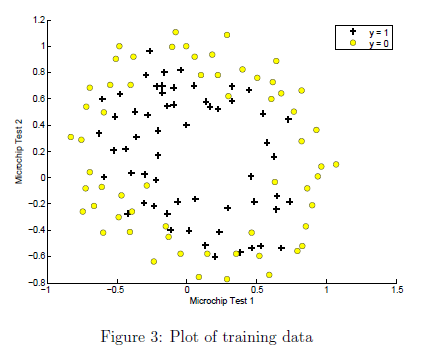

Run the code below and confirm you plot matches Figure 3.

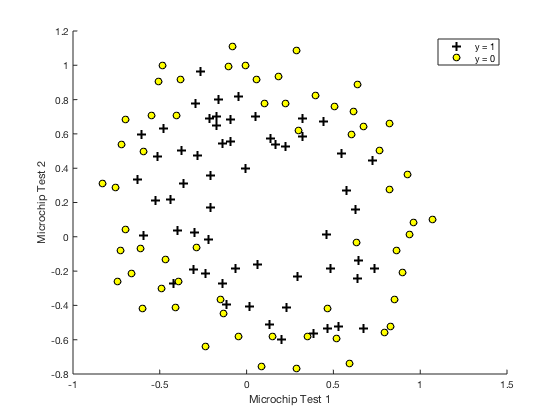

%  The first two columns contains the X values and the third column
%  contains the label (y).
data = load('ex2data2.txt');
X = data(:, [1, 2]); y = data(:, 3);

plotData(X, y);
% Put some labels 
hold on;
% Labels and Legend
xlabel('Microchip Test 1')
ylabel('Microchip Test 2')
% Specified in plot order
legend('y = 1', 'y = 0')
hold off;

        Figure 3 shows that our dataset cannot be separated into positive and negative examples by a straight-line through the plot. Therefore, a straightforward application of logistic regression will not perform well on this dataset since logistic regression will only be able to find a linear decision boundary.

### 2.2 Feature mapping

One way to fit the data better is to create more features from each data point. In the provided function `mapFeature.m`, we will map the features into all polynomial terms of $x_1$ and $x_2$ up to the sixth power.


$$\mathrm{mapFeature}\left(x\right)=\left\lbrack \begin{array}{c}
1\\
x_1 \\
x_2 \\
x_1^2 \\
x_1 x_2 \\
x_2^2 \\
x_1^3 \\
\vdots \;\\
x_1 x_2^5 \\
x_2^6 
\end{array}\right\rbrack$$


    As a result of this mapping, our vector of two features (the scores on two QA tests) has been transformed into a 28-dimensional vector. A logistic regression classifier trained on this higher-dimension feature vector will have a more complex decision boundary and will appear nonlinear when drawn in our 2-dimensional plot. 

    Run the code below to map the features.

% Add Polynomial Features
% Note that mapFeature also adds a column of ones for us, so the intercept term is handled
X = mapFeature(X(:,1), X(:,2));

    While the feature mapping allows us to build a more expressive classifier, it also more susceptible to overfitting. In the next parts of the exercise, you will implement regularized logistic regression to fit the data and also see for yourself how regularization can help combat the overfitting problem.

### 2.3 Cost function and gradient

Now you will implement code to compute the cost function and gradient for regularized logistic regression. Complete the code in `costFunctionReg.m` to return the cost and gradient. Recall that the regularized cost function in logistic regression is


$$J(\theta) =\frac{1}{m}\sum_{i=1}^m{\left[
-y^{(i)} \log(h_{\theta}(x^{(i)}))-(1-y^{(i)}) \log(1-h_{\theta}(x^{(i)}))\right]+\frac{\lambda}{2m}\sum_{j=1}^n{\theta_j^2},$$


Note that you should not regularize the parameter $\theta_0$. In MATLAB, recall that indexing starts from 1, hence, you should not be regularizing the `theta(1)` parameter (which corresponds to $\theta_0$) in the code. The gradient of the cost function is a vector where the $j\mathrm{th}$ element is defined as follows:


$$\frac{\partial J(\theta)}{\partial \theta_j} = \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}\qquad \mathrm{for}\;j=0,$$



$$\frac{\partial J(\theta)}{\partial \theta_j} = \left( \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}} \right)+\frac{\lambda}{m}\theta_j\qquad \mathrm{for}\;j\geq1,$$


Once you are done, run the code below to call your `costFunctionReg` function using the initial value of $\theta$ (initialized to all zeros). You should see that the cost is about 0.693.

% Initialize fitting parameters
initial_theta = zeros(size(X, 2), 1);

% Set regularization parameter lambda to 1
lambda = 1;

% Compute and display initial cost and gradient for regularized logistic regression
[cost, grad] = costFunctionReg(initial_theta, X, y, lambda);

grad =     0.0085
    0.0188
    0.0001
    0.0503
    0.0115
    0.0377
    0.0184
    0.0073
    0.0082
    0.0235


fprintf('Cost at initial theta (zeros): %f\n', cost);

Cost at initial theta (zeros): 0.693147


*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

#### 2.3.1 Learning parameters using `fminunc`

Similar to the previous parts, the next step is to use `fminunc` to learn the optimal parameters. If you have completed the cost and gradient for regularized logistic regression (`costFunctionReg.m`) correctly, you should be able to run the code in the following sections to learn the parameters using `fminunc` for multiple values of $\lambda$.

### 2.4 Plotting the decision boundary

To help you visualize the model learned by this classifier, we have provided the function `plotDecisionBoundary.m` which plots the (nonlinear) decision boundary that separates the positive and negative examples. In `plotDecisionBoundary.m`, we plot the nonlinear decision boundary by computing the classifier's predictions on an evenly spaced grid and then drew a contour plot of where the predictions change from $y = 0$ to $y = 1$. After learning the parameters, the code in the next section will plot a decision boundary similar to Figure 4.

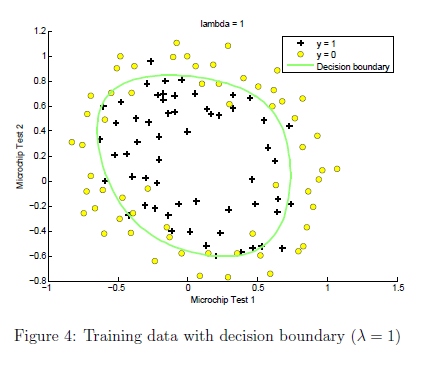

### 2.5 Optional (ungraded) exercises

In this part of the exercise, you will get to try out different regularization parameters for the dataset to understand how regularization prevents overfitting. Notice the changes in the decision boundary as you vary $\lambda$. With a small $\lambda$, you should find that the classifier gets almost every training example correct, but draws a very complicated boundary, thus overfitting the data (Figure 5). 

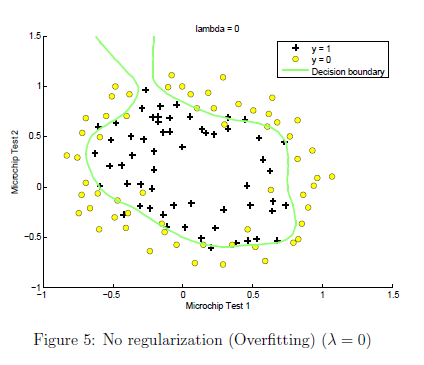

    This is not a good decision boundary: for example, it predicts that a point at $x = (0.25, 1.5)$ is accepted $(y = 1)$, which seems to be an incorrect decision given the training set. With a larger $\lambda$, you should see a plot that shows an simpler decision boundary which still separates the positives and negatives fairly well. However, if $\lambda$ is set to too high a value, you will not get a good fit and the decision boundary will not follow the data so well, thus underfitting the data (Figure 6).

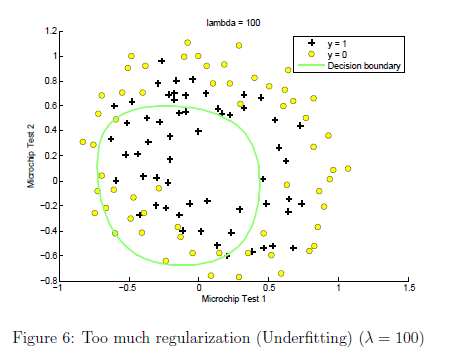

Use the control below to try the following values of $\lambda$: 0, 1, 10, 100. 

- How does the decision boundary change when you vary $\lambda$? 

- How does the training set accuracy vary?

% Initialize fitting parameters
initial_theta = zeros(size(X, 2), 1);

lambda = 0;
% Set Options
options = optimoptions(@fminunc,'Algorithm','Quasi-Newton','GradObj', 'on', 'MaxIter', 1000);

% Optimize
[theta, J, exit_flag] = fminunc(@(t)(costFunctionReg(t, X, y, lambda)), initial_theta, options);

grad =     0.0085
    0.0188
    0.0001
    0.0503
    0.0115
    0.0377
    0.0184
    0.0073
    0.0082
    0.0235


grad =    -0.0071
    0.0146
   -0.0064
    0.0451
    0.0113
    0.0305
    0.0153
    0.0063
    0.0075
    0.0182


grad =    -0.0568
   -0.0186
   -0.0345
    0.0192
    0.0086
   -0.0003
   -0.0061
    0.0018
    0.0022
   -0.0070


grad =    -0.0408
   -0.0356
   -0.0366
    0.0132
    0.0069
   -0.0036
   -0.0154
    0.0014
   -0.0005
   -0.0121


grad =    -0.0046
   -0.0457
   -0.0295
    0.0106
    0.0060
   -0.0000
   -0.0204
    0.0022
   -0.0021
   -0.0119


grad =     0.0145
   -0.0436
   -0.0211
    0.0073
    0.0066
    0.0028
   -0.0195
    0.0028
   -0.0021
   -0.0096


grad =     0.0183
   -0.0344
   -0.0128
    0.0023
    0.0079
    0.0035
   -0.0156
    0.0032
   -0.0012
   -0.0067


grad =     0.0124
   -0.0240
   -0.0065
   -0.0021
    0.0094
    0.0028
   -0.0115
    0.0032
    0.0001
   -0.0045


grad =     0.0034
   -0.0142
   -0.0022
   -0.0050
    0.0108
    0.0017
   -0.0079
    0.0031
    0.0014
   -0.0029


grad =    -0.0051
   -0.0056
    0.0006
   -0.0066
    0.0119
    0.0008
   -0.0049
    0.0030
    0.0026
   -0.0019


grad =    -0.0112
    0.0020
    0.0021
   -0.0068
    0.0126
    0.0005
   -0.0023
    0.0029
    0.0038
   -0.0013


grad =    -0.0132
    0.0085
    0.0025
   -0.0054
    0.0125
    0.0012
    0.0001
    0.0027
    0.0049
   -0.0009


grad =    -0.0092
    0.0130
    0.0018
   -0.0025
    0.0113
    0.0032
    0.0021
    0.0024
    0.0055
   -0.0008


grad =     0.0009
    0.0136
    0.0006
    0.0013
    0.0088
    0.0062
    0.0029
    0.0021
    0.0053
   -0.0006


grad =     0.0143
    0.0094
   -0.0002
    0.0046
    0.0051
    0.0093
    0.0019
    0.0019
    0.0040
   -0.0003


grad =     0.0225
    0.0042
    0.0004
    0.0056
    0.0019
    0.0107
    0.0002
    0.0019
    0.0023
    0.0002


grad =     0.0230
    0.0011
    0.0020
    0.0050
   -0.0007
    0.0103
   -0.0009
    0.0017
    0.0007
    0.0008


grad =     0.0161
    0.0003
    0.0032
    0.0032
   -0.0022
    0.0084
   -0.0012
    0.0014
   -0.0003
    0.0011


grad =     0.0070
    0.0003
    0.0035
    0.0014
   -0.0026
    0.0059
   -0.0012
    0.0011
   -0.0008
    0.0009


grad =    -0.0005
    0.0003
    0.0030
    0.0001
   -0.0027
    0.0038
   -0.0012
    0.0008
   -0.0011
    0.0004


grad =    -0.0056
    0.0001
    0.0018
   -0.0007
   -0.0026
    0.0023
   -0.0012
    0.0006
   -0.0012
   -0.0003


grad =    -0.0091
   -0.0002
    0.0002
   -0.0012
   -0.0024
    0.0010
   -0.0013
    0.0003
   -0.0012
   -0.0011


grad =    -0.0112
   -0.0007
   -0.0023
   -0.0014
   -0.0023
   -0.0003
   -0.0013
   -0.0000
   -0.0012
   -0.0021


grad =    -0.0110
   -0.0011
   -0.0058
   -0.0012
   -0.0021
   -0.0016
   -0.0012
   -0.0006
   -0.0011
   -0.0035


grad =    -0.0077
   -0.0009
   -0.0099
   -0.0005
   -0.0018
   -0.0027
   -0.0007
   -0.0013
   -0.0008
   -0.0050


grad =    -0.0021
    0.0004
   -0.0123
    0.0004
   -0.0014
   -0.0030
    0.0003
   -0.0019
   -0.0005
   -0.0056


grad =     0.0022
    0.0021
   -0.0114
    0.0008
   -0.0009
   -0.0025
    0.0014
   -0.0022
   -0.0003
   -0.0048


grad =     0.0039
    0.0032
   -0.0086
    0.0008
   -0.0003
   -0.0018
    0.0020
   -0.0020
   -0.0004
   -0.0032


grad =     0.0037
    0.0033
   -0.0047
    0.0004
    0.0003
   -0.0010
    0.0022
   -0.0016
   -0.0007
   -0.0012


grad =     0.0022
    0.0023
   -0.0010
   -0.0001
    0.0009
   -0.0003
    0.0019
   -0.0011
   -0.0011
    0.0008


grad =     0.0005
    0.0006
    0.0009
   -0.0006
    0.0013
   -0.0001
    0.0012
   -0.0007
   -0.0015
    0.0019


grad =    -0.0003
   -0.0005
    0.0009
   -0.0007
    0.0013
   -0.0002
    0.0008
   -0.0006
   -0.0017
    0.0019


grad =    -0.0002
   -0.0010
    0.0004
   -0.0007
    0.0013
   -0.0003
    0.0006
   -0.0006
   -0.0018
    0.0017


grad =     0.0004
   -0.0015
   -0.0004
   -0.0005
    0.0011
   -0.0003
    0.0004
   -0.0006
   -0.0018
    0.0014


grad =     0.0014
   -0.0023
   -0.0017
   -0.0002
    0.0008
   -0.0003
   -0.0000
   -0.0007
   -0.0018
    0.0008


grad =     0.0030
   -0.0035
   -0.0037
    0.0002
    0.0002
   -0.0001
   -0.0006
   -0.0009
   -0.0018
    0.0001


grad =     0.0051
   -0.0044
   -0.0061
    0.0005
   -0.0005
    0.0003
   -0.0014
   -0.0011
   -0.0016
   -0.0008


grad =     0.0064
   -0.0038
   -0.0075
    0.0004
   -0.0013
    0.0011
   -0.0018
   -0.0014
   -0.0011
   -0.0012


grad =     0.0046
   -0.0013
   -0.0062
   -0.0006
   -0.0012
    0.0017
   -0.0015
   -0.0015
   -0.0004
   -0.0006


grad =     0.0012
    0.0005
   -0.0036
   -0.0018
   -0.0006
    0.0015
   -0.0012
   -0.0013
   -0.0000
    0.0002


grad =    -0.0002
    0.0009
   -0.0020
   -0.0022
   -0.0003
    0.0015
   -0.0011
   -0.0012
   -0.0000
    0.0008


grad =    -0.0011
    0.0011
   -0.0012
   -0.0024
   -0.0001
    0.0013
   -0.0010
   -0.0011
   -0.0000
    0.0010


grad =    -0.0021
    0.0012
    0.0004
   -0.0023
    0.0002
    0.0010
   -0.0008
   -0.0008
   -0.0001
    0.0015


grad =    -0.0028
    0.0014
    0.0016
   -0.0017
    0.0004
    0.0002
   -0.0006
   -0.0005
   -0.0001
    0.0015


grad =    -0.0020
    0.0012
    0.0022
   -0.0003
    0.0005
   -0.0005
   -0.0005
   -0.0002
   -0.0001
    0.0013


grad =    -0.0008
    0.0008
    0.0011
    0.0007
    0.0003
   -0.0010
   -0.0005
   -0.0001
   -0.0001
    0.0005


grad = 	1.0e+-3 *

    0.0105
    0.4873
    0.2739
    0.9180
    0.1721
   -0.9916
   -0.6626
   -0.2031
   -0.0403
    0.2156


grad = 	1.0e+-3 *

    0.1956
    0.3570
   -0.0277
    0.8893
    0.1179
   -0.9407
   -0.7388
   -0.2431
   -0.0310
    0.1194


grad = 	1.0e+-3 *

    0.4444
    0.1580
   -0.3052
    0.8273
    0.0546
   -0.8239
   -0.8478
   -0.2811
   -0.0323
    0.0609


grad =     0.0008
   -0.0002
   -0.0007
    0.0007
   -0.0000
   -0.0006
   -0.0010
   -0.0003
   -0.0000
   -0.0000


grad =     0.0014
   -0.0008
   -0.0012
    0.0005
   -0.0002
   -0.0003
   -0.0013
   -0.0004
   -0.0001
   -0.0002


grad =     0.0022
   -0.0018
   -0.0019
    0.0002
   -0.0004
    0.0001
   -0.0017
   -0.0004
   -0.0002
   -0.0003


grad =     0.0029
   -0.0029
   -0.0024
   -0.0003
   -0.0006
    0.0007
   -0.0021
   -0.0003
   -0.0003
   -0.0005


grad =     0.0031
   -0.0035
   -0.0022
   -0.0007
   -0.0006
    0.0010
   -0.0019
   -0.0000
   -0.0005
   -0.0006


grad =     0.0023
   -0.0023
   -0.0009
   -0.0004
   -0.0002
    0.0007
   -0.0008
    0.0004
   -0.0006
   -0.0004


grad =     0.9359
   -0.6543
   -0.1164
   -0.0996
    0.0590
    0.1029
    0.0580
    0.5182
   -0.5881
   -0.3597


grad =     0.2077
   -0.1175
    0.0518
   -0.1022
    0.0839
   -0.0960
    0.2704
    0.4776
   -0.5605
   -0.3172


grad =    -0.0963
    0.1026
    0.0861
   -0.0927
    0.1067
   -0.1566
    0.3480
    0.4584
   -0.5298
   -0.3080


grad =    -0.5529
    0.4288
    0.0579
   -0.0853
    0.1530
   -0.2384
    0.4578
    0.4207
   -0.4634
   -0.3274


grad =    -0.0011
    0.0008
   -0.0000
   -0.0001
    0.0002
   -0.0003
    0.0006
    0.0004
   -0.0004
   -0.0004


grad =    -0.0018
    0.0014
   -0.0003
   -0.0001
    0.0003
   -0.0004
    0.0008
    0.0002
   -0.0002
   -0.0005


grad =    -0.0028
    0.0022
   -0.0008
   -0.0001
    0.0004
   -0.0005
    0.0011
   -0.0000
    0.0001
   -0.0006


grad =    -0.0035
    0.0029
   -0.0013
   -0.0002
    0.0004
   -0.0005
    0.0014
   -0.0004
    0.0005
   -0.0008


grad =    -0.0032
    0.0027
   -0.0015
   -0.0002
    0.0003
   -0.0003
    0.0013
   -0.0009
    0.0009
   -0.0008


grad =    -0.0018
    0.0012
   -0.0009
   -0.0003
    0.0001
   -0.0002
    0.0008
   -0.0011
    0.0009
   -0.0006


grad =    -0.5687
    0.0207
   -0.1341
   -0.1903
   -0.0099
   -0.2068
    0.3855
   -0.9364
    0.6660
   -0.3767


grad =    -0.0580
   -0.3160
    0.2214
   -0.1015
   -0.0848
   -0.1470
    0.2914
   -0.8455
    0.5374
   -0.2420


grad =     0.1803
   -0.4712
    0.4174
   -0.0540
   -0.1470
   -0.0851
    0.2443
   -0.7962
    0.4636
   -0.1578


grad =     0.5690
   -0.7155
    0.7694
    0.0343
   -0.2678
    0.0566
    0.1671
   -0.7124
    0.3410
    0.0035


grad =     0.0011
   -0.0010
    0.0013
    0.0002
   -0.0004
    0.0003
    0.0001
   -0.0006
    0.0002
    0.0002


grad =     0.0019
   -0.0015
    0.0021
    0.0004
   -0.0007
    0.0006
   -0.0001
   -0.0004
   -0.0001
    0.0006


grad =     0.0030
   -0.0022
    0.0032
    0.0007
   -0.0011
    0.0012
   -0.0004
   -0.0001
   -0.0004
    0.0012


grad =     0.0045
   -0.0030
    0.0048
    0.0011
   -0.0017
    0.0020
   -0.0007
    0.0003
   -0.0009
    0.0019


grad =     0.0061
   -0.0035
    0.0060
    0.0015
   -0.0023
    0.0029
   -0.0010
    0.0008
   -0.0013
    0.0026


grad =     0.0065
   -0.0029
    0.0056
    0.0016
   -0.0025
    0.0032
   -0.0010
    0.0011
   -0.0012
    0.0025


grad =     0.0040
   -0.0012
    0.0029
    0.0008
   -0.0017
    0.0021
   -0.0006
    0.0008
   -0.0006
    0.0014


grad =     0.0011
   -0.0001
    0.0005
   -0.0001
   -0.0007
    0.0006
   -0.0002
    0.0004
   -0.0002
    0.0004


grad =     0.3094
    0.1050
   -0.0432
   -0.3379
   -0.3979
   -0.0477
   -0.0936
    0.2881
   -0.0591
    0.1226


grad =     0.1365
    0.0891
   -0.1024
   -0.3464
   -0.3050
   -0.2240
   -0.0840
    0.2657
   -0.0337
    0.0581


grad =     0.0293
    0.0662
   -0.0832
   -0.3412
   -0.2618
   -0.3078
   -0.0844
    0.2605
   -0.0254
    0.0434


grad =    -0.2136
    0.0280
   -0.0275
   -0.3340
   -0.1893
   -0.4607
   -0.0866
    0.2537
   -0.0123
    0.0209


grad =    -0.5978
   -0.0215
    0.0815
   -0.3250
   -0.0896
   -0.6704
   -0.0900
    0.2455
    0.0050
    0.0034


grad =    -0.0013
   -0.0001
    0.0003
   -0.0003
    0.0001
   -0.0010
   -0.0001
    0.0002
    0.0000
   -0.0000


grad =    -0.0023
   -0.0002
    0.0006
   -0.0003
    0.0003
   -0.0015
   -0.0001
    0.0002
    0.0001
   -0.0000


grad =    -0.0037
   -0.0003
    0.0010
   -0.0003
    0.0006
   -0.0021
   -0.0001
    0.0002
    0.0001
   -0.0000


grad =    -0.0049
   -0.0004
    0.0015
   -0.0002
    0.0009
   -0.0026
   -0.0001
    0.0001
    0.0002
    0.0000


grad =    -0.0047
   -0.0003
    0.0017
   -0.0000
    0.0010
   -0.0023
    0.0000
   -0.0000
    0.0002
    0.0002


grad =    -0.0025
   -0.0000
    0.0010
   -0.0000
    0.0006
   -0.0011
    0.0001
   -0.0001
    0.0002
    0.0003


grad =    -0.6763
    0.0269
    0.2121
   -0.0918
    0.1736
   -0.3213
    0.0576
   -0.0676
    0.1153
    0.1907


grad =    -0.0744
   -0.0185
   -0.0195
   -0.0805
    0.0208
   -0.1034
    0.0205
   -0.0606
    0.0859
    0.1550


grad =     0.0462
   -0.0333
   -0.0508
   -0.0734
   -0.0165
   -0.0539
    0.0131
   -0.0562
    0.0739
    0.1630


grad =     0.0858
   -0.0330
   -0.0604
   -0.0700
   -0.0299
   -0.0313
    0.0140
   -0.0545
    0.0690
    0.1722


grad =     0.1367
   -0.0209
   -0.0773
   -0.0649
   -0.0426
    0.0034
    0.0205
   -0.0539
    0.0662
    0.1858


grad =     0.2150
    0.0124
   -0.1140
   -0.0567
   -0.0536
    0.0585
    0.0359
   -0.0565
    0.0692
    0.2015


grad =     0.3442
    0.0876
   -0.1956
   -0.0432
   -0.0610
    0.1489
    0.0677
   -0.0666
    0.0849
    0.2149


grad =     0.5427
    0.2356
   -0.3617
   -0.0227
   -0.0591
    0.2881
    0.1263
   -0.0927
    0.1245
    0.2127


grad =     0.8195
    0.5005
   -0.6743
    0.0058
   -0.0376
    0.4864
    0.2239
   -0.1487
    0.2031
    0.1651


grad =     0.0011
    0.0009
   -0.0012
    0.0000
    0.0000
    0.0007
    0.0004
   -0.0002
    0.0003
    0.0000


grad =     0.0011
    0.0013
   -0.0017
    0.0001
    0.0001
    0.0008
    0.0005
   -0.0004
    0.0004
   -0.0003


grad =     0.0006
    0.0013
   -0.0017
    0.0001
    0.0002
    0.0006
    0.0004
   -0.0004
    0.0004
   -0.0005


grad =    -0.0447
    0.8497
   -0.9448
    0.0244
    0.1839
    0.2005
    0.1835
   -0.3317
    0.1842
   -0.4401


grad =    -0.1633
    0.3726
   -0.3304
   -0.0034
    0.1102
    0.0055
    0.0115
   -0.2301
   -0.0304
   -0.2598


grad =    -0.1089
    0.1473
   -0.0899
   -0.0032
    0.0545
    0.0052
   -0.0642
   -0.1762
   -0.1278
   -0.1543


grad =    -0.0564
    0.0522
    0.0238
    0.0087
    0.0254
    0.0374
   -0.0950
   -0.1464
   -0.1725
   -0.0935


grad =    -0.0159
    0.0291
    0.0709
    0.0214
    0.0153
    0.0666
   -0.1015
   -0.1328
   -0.1883
   -0.0635


grad =     0.0203
    0.0312
    0.0928
    0.0324
    0.0128
    0.0900
   -0.0995
   -0.1262
   -0.1935
   -0.0465


grad =     0.0807
    0.0457
    0.1179
    0.0491
    0.0124
    0.1255
   -0.0926
   -0.1186
   -0.1972
   -0.0244


grad =     0.1784
    0.0742
    0.1519
    0.0741
    0.0140
    0.1797
   -0.0797
   -0.1084
   -0.2003
    0.0078


grad =     0.3420
    0.1242
    0.2049
    0.1137
    0.0181
    0.2682
   -0.0569
   -0.0925
   -0.2036
    0.0593


grad =     0.6030
    0.2049
    0.2870
    0.1746
    0.0255
    0.4081
   -0.0188
   -0.0670
   -0.2065
    0.1404


grad =     0.9967
    0.3257
    0.4089
    0.2639
    0.0368
    0.6186
    0.0423
   -0.0258
   -0.2077
    0.2625


grad =     0.0015
    0.0005
    0.0006
    0.0004
    0.0001
    0.0009
    0.0001
    0.0000
   -0.0002
    0.0004


grad =     0.0018
    0.0006
    0.0006
    0.0005
    0.0001
    0.0010
    0.0002
    0.0001
   -0.0002
    0.0005


grad =     0.0014
    0.0005
    0.0004
    0.0004
    0.0001
    0.0007
    0.0002
    0.0001
   -0.0001
    0.0002


grad =     0.6678
    0.1783
    0.1917
    0.2769
    0.0325
    0.2488
    0.1850
    0.1118
   -0.1099
   -0.0330


grad =     0.2164
    0.0271
    0.1153
    0.1142
    0.0118
    0.0677
    0.1291
    0.0665
   -0.1146
   -0.0969


grad =     0.0437
   -0.0006
    0.0446
    0.0584
    0.0054
    0.0003
    0.1064
    0.0411
   -0.1126
   -0.1353


grad =    -0.0091
   -0.0158
    0.0245
    0.0449
   -0.0004
   -0.0148
    0.0937
    0.0314
   -0.1129
   -0.1413


grad =    -0.0569
   -0.0352
    0.0034
    0.0349
   -0.0089
   -0.0285
    0.0775
    0.0220
   -0.1130
   -0.1490


grad =    -0.1077
   -0.0649
   -0.0144
    0.0247
   -0.0224
   -0.0385
    0.0537
    0.0114
   -0.1136
   -0.1535


grad =    -0.1771
   -0.1122
   -0.0343
    0.0103
   -0.0450
   -0.0479
    0.0152
   -0.0036
   -0.1139
   -0.1577


grad =    -0.2736
   -0.1848
   -0.0534
   -0.0112
   -0.0815
   -0.0533
   -0.0455
   -0.0254
   -0.1135
   -0.1580


grad =    -0.4158
   -0.2964
   -0.0714
   -0.0456
   -0.1399
   -0.0515
   -0.1420
   -0.0590
   -0.1110
   -0.1519


grad =    -0.6274
   -0.4645
   -0.0840
   -0.1011
   -0.2316
   -0.0350
   -0.2931
   -0.1110
   -0.1037
   -0.1324


grad =    -0.9416
   -0.7060
   -0.0866
   -0.1911
   -0.3694
    0.0083
   -0.5205
   -0.1907
   -0.0858
   -0.0885


grad =    -0.0014
   -0.0010
   -0.0001
   -0.0003
   -0.0006
    0.0001
   -0.0008
   -0.0003
   -0.0000
   -0.0000


grad =    -0.0018
   -0.0012
   -0.0001
   -0.0005
   -0.0007
    0.0003
   -0.0011
   -0.0004
    0.0000
    0.0001


grad =    -0.0017
   -0.0012
   -0.0001
   -0.0006
   -0.0008
    0.0005
   -0.0011
   -0.0005
    0.0001
    0.0003


grad =    -0.4676
   -0.7419
    0.0414
   -0.2439
   -0.5869
    0.5504
   -0.6495
   -0.3480
    0.0682
    0.4009


grad =     0.3392
   -0.2656
    0.1321
    0.0836
   -0.2779
    0.3265
   -0.1827
   -0.0878
    0.0219
    0.2727


grad =     0.0653
   -0.0937
    0.0282
    0.0912
   -0.0969
    0.0770
   -0.0213
    0.0077
    0.0214
    0.1059


grad =    -0.7025
   -0.4441
   -0.3246
    0.7635
   -0.6017
    0.1616
    0.1551
    0.1168
    0.2827
    0.5450


grad =    -0.5864
   -0.2510
   -0.4157
    0.8049
   -0.5801
    0.2627
    0.2736
    0.0471
    0.3221
    0.5519


grad =    -0.2217
   -0.1547
   -0.3875
    0.8513
   -0.5783
    0.4513
    0.3280
   -0.0106
    0.3515
    0.6443


grad =     0.2824
   -0.0660
   -0.3120
    0.8907
   -0.5612
    0.6935
    0.3745
   -0.0712
    0.3856
    0.7776


grad =     0.1070
    0.0060
   -0.0166
    0.0925
   -0.0515
    0.1065
    0.0437
   -0.0156
    0.0436
    0.0993


grad =     0.2244
    0.0254
    0.0081
    0.0941
   -0.0427
    0.1622
    0.0527
   -0.0278
    0.0511
    0.1325


grad =     0.4015
    0.0566
    0.0486
    0.0917
   -0.0274
    0.2476
    0.0667
   -0.0461
    0.0622
    0.1842


grad =     0.6616
    0.1062
    0.1123
    0.0812
   -0.0024
    0.3754
    0.0880
   -0.0734
    0.0784
    0.2624


grad =     0.0010
    0.0002
    0.0002
    0.0001
    0.0000
    0.0006
    0.0001
   -0.0001
    0.0001
    0.0004


grad =     0.0014
    0.0003
    0.0003
    0.0000
    0.0001
    0.0008
    0.0002
   -0.0002
    0.0001
    0.0005


grad =     0.0017
    0.0004
    0.0004
   -0.0001
    0.0001
    0.0009
    0.0002
   -0.0002
    0.0001
    0.0006


grad =     0.0013
    0.0003
    0.0004
   -0.0002
    0.0001
    0.0008
    0.0002
   -0.0002
    0.0001
    0.0005


grad =     0.5820
    0.1754
    0.1898
   -0.1559
    0.0635
    0.3714
    0.0457
   -0.0787
    0.0958
    0.1961


grad =     0.1031
    0.0301
    0.0679
   -0.0732
    0.0208
    0.0609
   -0.0279
    0.0033
    0.0663
   -0.0105


grad =    -0.1022
    0.0345
    0.2300
   -0.3253
    0.1732
   -0.1599
   -0.3257
    0.2309
    0.6418
   -0.6225


grad =    -0.1396
    0.0419
    0.1329
   -0.2435
    0.1880
   -0.1883
   -0.3061
    0.2145
    0.6775
   -0.6549


grad =    -0.0331
    0.0335
    0.1524
   -0.2062
    0.1984
   -0.1306
   -0.3112
    0.1920
    0.7032
   -0.6204


grad =     0.1834
    0.0195
    0.2253
   -0.1598
    0.2239
   -0.0332
   -0.3283
    0.1659
    0.7380
   -0.5599


grad =     0.4835
    0.0062
    0.3301
   -0.1053
    0.2664
    0.0777
   -0.3529
    0.1428
    0.7778
   -0.4943


grad =     0.9645
   -0.0118
    0.4888
   -0.0224
    0.3414
    0.2253
   -0.3940
    0.1167
    0.8344
   -0.4142


grad =     0.1668
   -0.0042
    0.0702
    0.0097
    0.0457
    0.0404
   -0.0459
    0.0087
    0.0909
   -0.0330


grad =     0.2705
   -0.0104
    0.0983
    0.0273
    0.0632
    0.0618
   -0.0568
    0.0047
    0.1010
   -0.0249


grad =     0.4170
   -0.0227
    0.1326
    0.0522
    0.0885
    0.0851
   -0.0744
   -0.0010
    0.1138
   -0.0198


grad =     0.6140
   -0.0457
    0.1693
    0.0860
    0.1235
    0.1058
   -0.1018
   -0.0100
    0.1287
   -0.0226


grad =     0.8462
   -0.0832
    0.1947
    0.1276
    0.1666
    0.1118
   -0.1397
   -0.0241
    0.1421
   -0.0432


grad =     0.0010
   -0.0001
    0.0002
    0.0002
    0.0002
    0.0001
   -0.0002
   -0.0000
    0.0001
   -0.0001


grad =     0.0010
   -0.0002
    0.0001
    0.0002
    0.0002
   -0.0000
   -0.0002
   -0.0001
    0.0001
   -0.0002


grad =     0.7044
   -0.1656
   -0.0607
    0.1835
    0.1064
   -0.1309
   -0.1320
   -0.0703
    0.0378
   -0.2539


grad =     0.2920
   -0.1545
   -0.0559
    0.0973
   -0.0149
   -0.0792
   -0.0475
   -0.0525
   -0.0556
   -0.1123


grad =    -0.0253
   -0.1007
   -0.0267
   -0.0140
   -0.0052
    0.0018
   -0.0036
   -0.0249
   -0.0624
    0.0199


grad =    -0.1292
   -0.0513
   -0.0718
   -0.0243
    0.0352
   -0.0371
    0.0131
   -0.0098
   -0.0326
   -0.0279


grad =    -0.7750
   -0.2120
   -0.3966
    0.0314
    0.4223
   -0.0859
    0.3136
   -0.0230
   -0.2103
   -0.1404


grad =    -0.2964
   -0.0760
   -0.1999
    0.1684
    0.4131
    0.1230
    0.3928
   -0.0282
   -0.1838
    0.0183


grad =     0.4486
    0.1313
    0.1088
    0.3556
    0.4289
    0.4344
    0.5050
   -0.0392
   -0.1326
    0.2594


grad =     0.1066
    0.0299
    0.0387
    0.0495
    0.0470
    0.0691
    0.0587
   -0.0039
   -0.0081
    0.0458


grad =     0.2280
    0.0626
    0.0975
    0.0750
    0.0588
    0.1198
    0.0737
   -0.0019
    0.0033
    0.0847


grad =     0.4000
    0.1094
    0.1855
    0.1097
    0.0793
    0.1921
    0.0936
    0.0029
    0.0207
    0.1399


grad =     0.6812
    0.1874
    0.3352
    0.1648
    0.1171
    0.3109
    0.1252
    0.0136
    0.0509
    0.2301


grad =     0.0011
    0.0003
    0.0006
    0.0002
    0.0002
    0.0005
    0.0002
    0.0000
    0.0001
    0.0004


grad =     0.0018
    0.0005
    0.0010
    0.0004
    0.0003
    0.0008
    0.0002
    0.0001
    0.0002
    0.0006


grad =     0.0028
    0.0008
    0.0015
    0.0006
    0.0005
    0.0012
    0.0004
    0.0001
    0.0003
    0.0009


grad =     0.0042
    0.0012
    0.0023
    0.0008
    0.0007
    0.0018
    0.0005
    0.0002
    0.0005
    0.0014


grad =     0.0055
    0.0016
    0.0031
    0.0011
    0.0009
    0.0024
    0.0006
    0.0003
    0.0006
    0.0018


grad =     0.0057
    0.0016
    0.0033
    0.0011
    0.0009
    0.0024
    0.0006
    0.0004
    0.0006
    0.0018


grad =     0.0039
    0.0009
    0.0022
    0.0008
    0.0006
    0.0016
    0.0003
    0.0003
    0.0004
    0.0012


grad =     0.0013
    0.0002
    0.0006
    0.0002
    0.0002
    0.0005
    0.0001
    0.0001
    0.0001
    0.0003


grad =     0.1180
   -0.0126
    0.0084
    0.0196
    0.0197
    0.0002
   -0.0008
    0.0469
    0.0199
    0.0341


grad =    -0.2771
   -0.1939
   -0.2352
   -0.0289
   -0.0011
   -0.2937
    0.0227
    0.3808
    0.0503
    0.1637


grad =    -0.1483
   -0.0612
   -0.1019
    0.0446
    0.0065
   -0.1813
    0.0745
    0.3999
    0.0712
    0.2182


grad =    -0.0276
    0.0082
   -0.0454
    0.1069
    0.0166
   -0.1272
    0.0999
    0.4133
    0.0887
    0.2350


grad =     0.1039
    0.0586
   -0.0169
    0.1762
    0.0256
   -0.0898
    0.1193
    0.4259
    0.1030
    0.2378


grad =     0.3059
    0.1042
   -0.0065
    0.2788
    0.0356
   -0.0516
    0.1395
    0.4418
    0.1173
    0.2299


grad =     0.6266
    0.1382
   -0.0244
    0.4327
    0.0461
   -0.0086
    0.1603
    0.4620
    0.1305
    0.2079


grad =     0.1150
    0.0147
   -0.0091
    0.0671
    0.0056
    0.0044
    0.0181
    0.0488
    0.0140
    0.0164


grad =     0.2000
    0.0105
   -0.0240
    0.1041
    0.0064
    0.0114
    0.0197
    0.0522
    0.0142
    0.0087


grad =     0.3381
   -0.0035
   -0.0530
    0.1620
    0.0063
    0.0208
    0.0201
    0.0564
    0.0127
   -0.0043


grad =     0.5608
   -0.0351
   -0.1056
    0.2526
    0.0045
    0.0340
    0.0181
    0.0613
    0.0080
   -0.0257


grad =     0.9126
   -0.0961
   -0.1963
    0.3923
   -0.0007
    0.0528
    0.0116
    0.0661
   -0.0023
   -0.0598


grad =     0.0014
   -0.0002
   -0.0003
    0.0006
   -0.0000
    0.0001
   -0.0000
    0.0001
   -0.0000
   -0.0001


grad =     0.0020
   -0.0003
   -0.0005
    0.0008
   -0.0000
    0.0001
   -0.0000
    0.0001
   -0.0000
   -0.0002


grad =     0.0023
   -0.0004
   -0.0007
    0.0009
   -0.0000
    0.0001
   -0.0000
    0.0000
   -0.0001
   -0.0002


grad =     0.0015
   -0.0004
   -0.0006
    0.0006
   -0.0000
    0.0001
   -0.0001
   -0.0000
   -0.0001
   -0.0002


grad =     0.4262
   -0.1606
   -0.1790
    0.1674
   -0.0280
   -0.0091
   -0.0530
   -0.0032
   -0.0241
   -0.0826


grad =     0.3431
   -0.4259
   -0.0363
    0.0693
   -0.1284
    0.0173
   -0.2536
   -0.0566
   -0.0827
    0.0229


grad =    -0.3465
   -0.0656
   -0.0600
   -0.1166
    0.0145
   -0.0890
   -0.1340
   -0.0906
    0.0149
   -0.0308


grad =    -0.1558
   -0.0267
    0.0050
   -0.0499
    0.0151
    0.0521
   -0.0987
   -0.0924
    0.0226
    0.0781


grad =    -0.1564
    0.0263
   -0.0741
    0.1165
    0.1744
    0.7503
   -0.8213
   -0.9171
    0.3176
    0.7309


grad =     0.1133
    0.0391
    0.0001
    0.0705
    0.0175
    0.1015
   -0.0636
   -0.0893
    0.0413
    0.0755


grad =     0.3028
    0.1121
    0.0231
    0.1624
    0.0191
    0.1422
   -0.0298
   -0.0837
    0.0589
    0.0795


grad =     0.5700
    0.2357
    0.0680
    0.2978
    0.0240
    0.2024
    0.0248
   -0.0729
    0.0878
    0.0856


grad =     0.9755
    0.4465
    0.1496
    0.5095
    0.0355
    0.2962
    0.1154
   -0.0526
    0.1366
    0.0944


grad =     0.1592
    0.0794
    0.0289
    0.0838
    0.0059
    0.0441
    0.0262
   -0.0016
    0.0216
    0.0106


grad =     0.2546
    0.1362
    0.0522
    0.1356
    0.0103
    0.0669
    0.0499
    0.0047
    0.0347
    0.0123


grad =     0.4030
    0.2284
    0.0907
    0.2170
    0.0182
    0.1025
    0.0881
    0.0154
    0.0559
    0.0145


grad =     0.6334
    0.3756
    0.1529
    0.3443
    0.0320
    0.1580
    0.1489
    0.0331
    0.0898
    0.0174


grad =     0.9827
    0.6039
    0.2507
    0.5384
    0.0547
    0.2426
    0.2430
    0.0616
    0.1426
    0.0213


grad =     0.0015
    0.0009
    0.0004
    0.0008
    0.0001
    0.0004
    0.0004
    0.0001
    0.0002
    0.0000


grad =     0.0020
    0.0013
    0.0006
    0.0011
    0.0001
    0.0005
    0.0005
    0.0002
    0.0003
    0.0000


grad =     0.0023
    0.0015
    0.0007
    0.0013
    0.0002
    0.0006
    0.0006
    0.0002
    0.0004
    0.0000


grad =     0.0017
    0.0012
    0.0005
    0.0010
    0.0001
    0.0004
    0.0005
    0.0001
    0.0003
    0.0000


grad =     0.6865
    0.4872
    0.1740
    0.4008
    0.0127
    0.1588
    0.2449
    0.0349
    0.1044
    0.0122


grad =     0.1207
    0.0805
   -0.0001
    0.0729
   -0.0157
    0.0041
    0.0820
   -0.0141
    0.0188
   -0.0079


grad =     0.0775
   -0.0897
   -0.2393
   -0.0043
   -0.1042
   -0.1245
    0.4148
   -0.1763
    0.0590
   -0.0699


grad =     0.0261
   -0.1089
   -0.1208
   -0.0501
   -0.0565
   -0.0350
    0.3698
   -0.1351
    0.0813
   -0.0216


grad =     0.0194
   -0.0768
   -0.0104
   -0.0488
   -0.0287
    0.0203
    0.3591
   -0.1046
    0.0994
    0.0115


grad =    -0.0016
   -0.0621
    0.0592
   -0.0538
   -0.0104
    0.0422
    0.3497
   -0.0849
    0.1082
    0.0272


grad =    -0.0473
   -0.0560
    0.1346
   -0.0691
    0.0145
    0.0536
    0.3331
   -0.0599
    0.1163
    0.0370


grad =    -0.1298
   -0.0616
    0.2214
   -0.0994
    0.0524
    0.0519
    0.3051
   -0.0248
    0.1246
    0.0383


grad =    -0.2786
   -0.0860
    0.3342
   -0.1564
    0.1155
    0.0298
    0.2562
    0.0305
    0.1343
    0.0261


grad =    -0.5331
   -0.1409
    0.4845
   -0.2561
    0.2188
   -0.0263
    0.1748
    0.1170
    0.1459
   -0.0085


grad =    -0.9623
   -0.2463
    0.6934
   -0.4264
    0.3878
   -0.1391
    0.0407
    0.2544
    0.1600
   -0.0804


grad =    -0.1669
   -0.0432
    0.0990
   -0.0709
    0.0660
   -0.0343
   -0.0176
    0.0471
    0.0177
   -0.0212


grad =    -0.2803
   -0.0744
    0.1413
   -0.1165
    0.1089
   -0.0691
   -0.0520
    0.0807
    0.0197
   -0.0435


grad =    -0.4546
   -0.1241
    0.2006
   -0.1870
    0.1740
   -0.1244
   -0.1046
    0.1312
    0.0217
   -0.0788


grad =    -0.7012
   -0.1995
    0.2784
   -0.2878
    0.2646
   -0.2040
   -0.1806
    0.2016
    0.0219
   -0.1281


grad =    -0.9958
   -0.3074
    0.3645
   -0.4107
    0.3701
   -0.2988
   -0.2794
    0.2851
    0.0150
   -0.1810


grad =    -0.0012
   -0.0004
    0.0004
   -0.0005
    0.0004
   -0.0004
   -0.0004
    0.0004
   -0.0000
   -0.0002


grad =    -0.0013
   -0.0005
    0.0004
   -0.0005
    0.0004
   -0.0004
   -0.0004
    0.0003
   -0.0000
   -0.0002


grad =    -0.7196
   -0.3307
    0.1845
   -0.2491
    0.2104
   -0.2374
   -0.2448
    0.1800
   -0.0238
   -0.1128


grad =     0.1540
    0.3508
   -0.3748
    0.5759
   -0.1873
   -0.3932
    0.1992
   -0.0896
    0.2085
   -0.6462


grad =    -0.0077
    0.1185
   -0.2401
    0.0618
   -0.0078
   -0.2091
   -0.0350
    0.0287
    0.0538
   -0.3112


grad =    -0.0310
    0.0112
   -0.1592
   -0.0287
   -0.0108
   -0.0282
   -0.0346
    0.0233
   -0.0202
   -0.0668


grad =     0.1089
   -0.0926
   -0.5490
   -0.1176
   -0.0326
    0.0798
   -0.4291
    0.4790
   -0.2829
   -0.1542


grad =     0.1660
   -0.0029
    0.0178
    0.0054
   -0.0297
    0.2372
   -0.3985
    0.5810
   -0.2749
    0.0832


grad =     0.0620
    0.0880
    0.1860
    0.0298
   -0.0323
    0.2586
   -0.3693
    0.6050
   -0.2598
    0.1388


grad =    -0.4317
    0.4579
    0.6781
    0.0678
   -0.0456
    0.2855
   -0.2502
    0.6681
   -0.1964
    0.2826


grad =    -0.1129
    0.0935
    0.1214
    0.0081
   -0.0055
    0.0280
   -0.0093
    0.0730
   -0.0117
    0.0424


grad =    -0.2483
    0.1831
    0.2104
    0.0044
   -0.0064
    0.0233
    0.0206
    0.0830
    0.0030
    0.0644


grad =    -0.4629
    0.3186
    0.3344
   -0.0073
   -0.0049
    0.0107
    0.0668
    0.0963
    0.0243
    0.0933


grad =    -0.8233
    0.5419
    0.5225
   -0.0383
    0.0006
   -0.0157
    0.1437
    0.1167
    0.0590
    0.1352


grad =    -0.1398
    0.0885
    0.0792
   -0.0100
    0.0016
   -0.0068
    0.0264
    0.0145
    0.0110
    0.0191


grad =    -0.2327
    0.1430
    0.1188
   -0.0223
    0.0049
   -0.0164
    0.0458
    0.0187
    0.0190
    0.0270


grad =    -0.3779
    0.2254
    0.1742
   -0.0443
    0.0115
   -0.0337
    0.0758
    0.0245
    0.0304
    0.0370


grad =    -0.6026
    0.3509
    0.2515
   -0.0834
    0.0233
   -0.0628
    0.1219
    0.0326
    0.0476
    0.0500


grad =    -0.9240
    0.5239
    0.3459
   -0.1453
    0.0438
   -0.1101
    0.1875
    0.0418
    0.0699
    0.0629


grad =    -0.0013
    0.0007
    0.0004
   -0.0002
    0.0001
   -0.0002
    0.0003
    0.0000
    0.0001
    0.0001


grad =    -0.0016
    0.0009
    0.0005
   -0.0003
    0.0001
   -0.0002
    0.0003
    0.0000
    0.0001
    0.0001


grad =    -0.0015
    0.0008
    0.0003
   -0.0003
    0.0001
   -0.0002
    0.0003
    0.0000
    0.0001
    0.0000


grad =    -0.6428
    0.3345
    0.1058
   -0.1616
    0.0684
   -0.1352
    0.1355
    0.0242
    0.0354
   -0.0150


grad =    -0.7640
    0.5849
    0.3589
   -0.3597
    0.1890
   -0.3115
    0.2219
    0.1677
    0.0687
   -0.0613


grad =     0.6963
   -0.2819
   -0.1164
    0.1243
    0.0629
   -0.0123
   -0.0431
   -0.0473
   -0.0422
   -0.0550


grad =     0.6941
   -0.4702
   -0.0049
   -0.0341
    0.1086
   -0.3297
   -0.0365
   -0.2395
   -0.0998
   -0.1028


grad =     0.2305
   -0.3538
   -0.2994
    0.1125
    0.1038
   -0.4191
    0.0798
   -0.3821
   -0.1460
   -0.2611


grad =    -0.0221
   -0.0716
   -0.1700
    0.2119
    0.0666
   -0.3634
    0.1819
   -0.4199
   -0.0603
   -0.2522


grad =    -0.3760
    0.2984
    0.2606
    0.3527
    0.0018
   -0.2079
    0.2784
   -0.4278
    0.0620
   -0.1380


grad =    -0.5847
    0.6538
    0.7108
    0.5239
   -0.0769
   -0.0420
    0.3732
   -0.4263
    0.1728
    0.0016


grad =    -0.0921
    0.1240
    0.1628
    0.0853
   -0.0230
    0.0282
    0.0513
   -0.0400
    0.0366
    0.0297


grad =    -0.1230
    0.2090
    0.2995
    0.1399
   -0.0475
    0.0777
    0.0722
   -0.0354
    0.0643
    0.0748


grad =    -0.1598
    0.3403
    0.5273
    0.2326
   -0.0880
    0.1596
    0.1031
   -0.0251
    0.1083
    0.1504


grad =    -0.1905
    0.5462
    0.8890
    0.3882
   -0.1536
    0.2913
    0.1523
   -0.0068
    0.1774
    0.2710


grad =    -0.0215
    0.0870
    0.1475
    0.0645
   -0.0259
    0.0505
    0.0229
    0.0027
    0.0288
    0.0466


grad =    -0.0213
    0.1385
    0.2415
    0.1070
   -0.0428
    0.0849
    0.0351
    0.0084
    0.0464
    0.0779


grad =    -0.0169
    0.2197
    0.3922
    0.1758
   -0.0696
    0.1401
    0.0543
    0.0182
    0.0743
    0.1281


grad =    -0.0048
    0.3462
    0.6296
    0.2852
   -0.1114
    0.2269
    0.0841
    0.0346
    0.1181
    0.2071


grad =     0.0165
    0.5311
    0.9869
    0.4491
   -0.1726
    0.3561
    0.1270
    0.0609
    0.1827
    0.3259


grad =     0.0000
    0.0008
    0.0015
    0.0007
   -0.0002
    0.0005
    0.0002
    0.0001
    0.0003
    0.0005


grad =     0.0000
    0.0009
    0.0018
    0.0008
   -0.0003
    0.0007
    0.0002
    0.0001
    0.0003
    0.0006


grad =    -0.0000
    0.0008
    0.0016
    0.0008
   -0.0003
    0.0006
    0.0002
    0.0001
    0.0003
    0.0005


grad =     0.0288
    0.5533
    0.7234
    0.4195
   -0.1680
    0.3161
    0.1626
    0.0366
    0.1812
    0.2200


grad =     0.1165
    0.2283
    0.0666
    0.1446
   -0.0694
    0.0732
    0.0897
   -0.0210
    0.0792
   -0.0101


grad =     0.9142
    0.5112
   -0.6375
    0.3158
   -0.2119
   -0.0021
    0.3197
   -0.1911
    0.2521
   -0.4051


grad =     0.4566
    0.0505
   -0.3698
    0.0352
   -0.0449
   -0.0483
    0.1065
   -0.0842
    0.1026
   -0.2380


grad =     0.1328
   -0.0248
   -0.0784
   -0.0264
    0.0107
   -0.0236
    0.0382
   -0.0188
    0.0694
   -0.1144


grad =     0.1380
   -0.1053
    0.1814
   -0.2672
    0.1422
   -0.1796
    0.2998
   -0.0166
    0.7119
   -0.8208


grad =    -0.1650
   -0.0377
    0.3295
   -0.2438
    0.1025
   -0.2175
    0.3015
    0.0021
    0.7338
   -0.7947


grad =    -0.3291
   -0.0368
    0.3568
   -0.2337
    0.0548
   -0.2733
    0.2959
    0.0000
    0.7441
   -0.8066


grad =    -0.5233
   -0.0904
    0.3483
   -0.2254
   -0.0301
   -0.3734
    0.2737
   -0.0126
    0.7508
   -0.8397


grad =    -0.7662
   -0.2276
    0.3051
   -0.2170
   -0.1676
   -0.5340
    0.2235
   -0.0366
    0.7514
   -0.8971


grad =    -0.1098
   -0.0505
    0.0211
   -0.0203
   -0.0396
   -0.0800
    0.0125
   -0.0077
    0.0743
   -0.0995


grad =    -0.1552
   -0.1012
    0.0036
   -0.0178
   -0.0765
   -0.1232
   -0.0053
   -0.0141
    0.0718
   -0.1156


grad =    -0.2179
   -0.1902
   -0.0270
   -0.0128
   -0.1360
   -0.1936
   -0.0363
   -0.0237
    0.0665
   -0.1423


grad =    -0.3037
   -0.3423
   -0.0792
   -0.0032
   -0.2310
   -0.3076
   -0.0891
   -0.0379
    0.0563
   -0.1858


grad =    -0.4193
   -0.5979
   -0.1665
    0.0149
   -0.3819
   -0.4912
   -0.1775
   -0.0586
    0.0380
   -0.2564


grad =    -0.0571
   -0.1020
   -0.0311
    0.0048
   -0.0619
   -0.0784
   -0.0323
   -0.0088
    0.0006
   -0.0370


grad =    -0.0760
   -0.1702
   -0.0545
    0.0108
   -0.0987
   -0.1243
   -0.0557
   -0.0131
   -0.0047
   -0.0549


grad =    -0.0982
   -0.2760
   -0.0920
    0.0209
   -0.1531
   -0.1936
   -0.0920
   -0.0192
   -0.0130
   -0.0825


grad =    -0.1244
   -0.4258
   -0.1480
    0.0348
   -0.2262
   -0.2897
   -0.1431
   -0.0273
   -0.0244
   -0.1222


grad =    -0.1675
   -0.5889
   -0.2110
    0.0410
   -0.2981
   -0.3950
   -0.2003
   -0.0325
   -0.0360
   -0.1670


grad =    -0.1994
   -0.6338
   -0.2137
    0.0159
   -0.3029
   -0.4169
   -0.2248
   -0.0129
   -0.0424
   -0.1789


grad =     0.0314
   -0.4395
   -0.1127
   -0.0051
   -0.2057
   -0.2148
   -0.1808
    0.0493
   -0.0272
   -0.1436


grad =    -0.1205
   -0.2809
    0.3250
   -0.0349
    0.0458
   -0.2743
   -0.1211
    0.1193
   -0.0386
    0.1027


grad =     0.2603
   -0.0553
   -0.0341
   -0.0108
   -0.0023
    0.0421
   -0.0289
    0.0463
   -0.0582
    0.0617


grad =     0.2594
   -0.0526
    0.0207
    0.0200
   -0.0139
    0.0638
   -0.0088
    0.0216
   -0.0260
    0.0562


grad =     0.8143
    0.0705
    0.2458
    0.1317
    0.0584
    0.2395
    0.0148
    0.1677
    0.0205
    0.2810


grad =    -0.0918
    0.0213
   -0.0303
    0.0249
    0.1448
   -0.1111
   -0.0221
    0.1191
    0.0630
    0.0685


grad =    -0.0616
   -0.0630
   -0.0512
   -0.0107
    0.0716
   -0.0526
   -0.0247
    0.1069
    0.0181
    0.1039


grad =     0.0076
   -0.0311
   -0.0532
   -0.0126
    0.0404
   -0.0116
    0.0006
    0.1057
    0.0045
    0.1303


grad =     0.0255
   -0.0004
   -0.0307
   -0.0135
    0.0318
    0.0100
    0.0152
    0.1083
    0.0042
    0.1444


grad =     0.0204
    0.0467
    0.0017
   -0.0152
    0.0295
    0.0273
    0.0325
    0.1125
    0.0091
    0.1573


grad =    -0.0093
    0.1100
    0.0492
   -0.0191
    0.0301
    0.0448
    0.0531
    0.1175
    0.0181
    0.1722


grad =    -0.0806
    0.2075
    0.1237
   -0.0275
    0.0332
    0.0660
    0.0823
    0.1235
    0.0341
    0.1929


grad =    -0.2187
    0.3560
    0.2372
   -0.0437
    0.0384
    0.0925
    0.1243
    0.1294
    0.0603
    0.2221


grad =    -0.4716
    0.5882
    0.4124
   -0.0740
    0.0462
    0.1272
    0.1876
    0.1340
    0.1034
    0.2647


grad =    -0.9136
    0.9525
    0.6816
   -0.1287
    0.0575
    0.1731
    0.2845
    0.1344
    0.1734
    0.3272


grad =    -0.1667
    0.1527
    0.1096
   -0.0225
    0.0074
    0.0235
    0.0435
    0.0125
    0.0287
    0.0420


grad =    -0.2920
    0.2433
    0.1731
   -0.0389
    0.0099
    0.0318
    0.0669
    0.0098
    0.0469
    0.0557


grad =    -0.4957
    0.3846
    0.2696
   -0.0661
    0.0138
    0.0430
    0.1030
    0.0039
    0.0759
    0.0757


grad =    -0.8156
    0.6002
    0.4125
   -0.1093
    0.0204
    0.0572
    0.1577
   -0.0076
    0.1210
    0.1042


grad =    -0.0013
    0.0009
    0.0006
   -0.0002
    0.0000
    0.0001
    0.0002
   -0.0000
    0.0002
    0.0001


grad =    -0.0019
    0.0013
    0.0009
   -0.0003
    0.0001
    0.0001
    0.0003
   -0.0001
    0.0003
    0.0002


grad =    -0.0025
    0.0017
    0.0010
   -0.0003
    0.0001
    0.0001
    0.0004
   -0.0001
    0.0004
    0.0002


grad =    -0.0026
    0.0016
    0.0010
   -0.0004
    0.0002
   -0.0000
    0.0004
   -0.0001
    0.0004
    0.0002


grad =    -0.0020
    0.0010
    0.0006
   -0.0003
    0.0000
    0.0000
    0.0003
   -0.0001
    0.0002
    0.0002


grad =    -0.7736
    0.3062
    0.2086
   -0.2157
   -0.1236
    0.2008
    0.1273
   -0.0853
    0.0321
    0.1665


grad =     0.0813
    0.0977
   -0.0141
   -0.1163
   -0.0619
    0.1479
    0.0313
   -0.0325
   -0.0130
    0.0730


grad =     0.1605
    0.0916
   -0.1172
   -0.0260
   -0.0170
    0.0277
    0.0178
   -0.0186
    0.0016
   -0.0310


grad =    -0.1725
    0.3375
   -0.3333
   -0.1176
    0.0627
   -0.4124
   -0.0707
   -0.0569
   -0.0157
   -0.0963


grad =    -0.1495
    0.0230
   -0.1648
   -0.0220
    0.0248
   -0.1689
   -0.1902
   -0.0524
   -0.0062
   -0.0441


grad =    -0.1309
    0.0719
    0.0425
    0.0122
   -0.0171
   -0.1003
   -0.1644
   -0.0798
   -0.0020
    0.1025


grad =    -0.0018
    0.0348
    0.0271
    0.0053
   -0.0238
   -0.0644
   -0.1816
   -0.0804
   -0.0148
    0.1183


grad =     0.0836
    0.0089
    0.0084
    0.0076
   -0.0332
   -0.0390
   -0.1949
   -0.0875
   -0.0168
    0.1203


grad =     0.2135
   -0.0369
   -0.0563
    0.0077
   -0.0517
   -0.0083
   -0.2214
   -0.1090
   -0.0161
    0.1076


grad =     0.3256
   -0.0904
   -0.1491
   -0.0005
   -0.0719
    0.0119
   -0.2538
   -0.1392
   -0.0126
    0.0826


grad =     0.4737
   -0.1774
   -0.3255
   -0.0221
   -0.1018
    0.0288
   -0.3080
   -0.1954
   -0.0048
    0.0301


grad =     0.6478
   -0.3024
   -0.6051
   -0.0627
   -0.1387
    0.0358
   -0.3863
   -0.2832
    0.0090
   -0.0570


grad =     0.0868
   -0.0488
   -0.1066
   -0.0134
   -0.0182
    0.0024
   -0.0502
   -0.0425
    0.0033
   -0.0205


grad =     0.1139
   -0.0750
   -0.1800
   -0.0250
   -0.0223
   -0.0023
   -0.0667
   -0.0646
    0.0076
   -0.0448


grad =     0.1468
   -0.1113
   -0.2969
   -0.0434
   -0.0243
   -0.0138
   -0.0893
   -0.0986
    0.0152
   -0.0847


grad =     0.1838
   -0.1586
   -0.4806
   -0.0717
   -0.0199
   -0.0380
   -0.1189
   -0.1501
    0.0283
   -0.1492


grad =     0.2147
   -0.2136
   -0.7640
   -0.1151
   -0.0006
   -0.0848
   -0.1542
   -0.2258
    0.0512
   -0.2519


grad =     0.0002
   -0.0003
   -0.0012
   -0.0002
    0.0000
   -0.0002
   -0.0002
   -0.0003
    0.0001
   -0.0004


grad =     0.0000
   -0.0003
   -0.0017
   -0.0003
    0.0001
   -0.0003
   -0.0002
   -0.0004
    0.0001
   -0.0006


grad =    -0.0004
   -0.0002
   -0.0021
   -0.0004
    0.0003
   -0.0005
   -0.0002
   -0.0005
    0.0002
   -0.0008


grad =    -0.0005
   -0.0003
   -0.0018
   -0.0003
    0.0003
   -0.0005
   -0.0002
   -0.0004
    0.0002
   -0.0007


grad =     0.3285
   -0.3197
   -0.8210
    0.0285
    0.2096
   -0.0925
   -0.1158
   -0.1299
    0.0678
   -0.2890


grad =     0.6067
   -0.1789
   -0.2364
    0.1803
    0.0273
    0.0561
   -0.0349
   -0.0256
    0.0005
   -0.0680


grad =     0.3151
   -0.0695
   -0.0487
    0.0980
   -0.0136
    0.0304
   -0.0004
   -0.0084
   -0.0112
   -0.0131


grad =     0.9559
   -0.2448
    0.0339
    0.2905
   -0.1687
    0.1138
    0.0477
   -0.0613
   -0.0956
    0.0529


grad =    -0.0196
    0.0031
    0.1650
   -0.0315
   -0.0624
    0.0275
    0.0310
   -0.0401
   -0.0258
    0.0887


grad =    -0.1801
   -0.0072
    0.1218
   -0.0953
   -0.0100
    0.0242
   -0.0178
   -0.0191
    0.0064
    0.0683


grad =    -0.6505
   -0.1589
    0.3874
   -0.4913
    0.0419
    0.1404
   -0.2482
   -0.0961
    0.1436
    0.2622


grad =     0.2190
   -0.2573
   -0.0020
   -0.1187
    0.0074
    0.1407
   -0.2072
   -0.0552
    0.1211
    0.0823


grad =     0.4422
   -0.1023
   -0.1398
    0.0638
   -0.0334
    0.0998
   -0.0970
   -0.0439
    0.1036
    0.0173


grad =     0.2716
    0.0022
   -0.0708
    0.0564
   -0.0447
    0.0977
   -0.0514
   -0.0426
    0.1006
    0.0566


grad =     0.0559
    0.0602
   -0.0136
    0.0117
   -0.0442
    0.0839
   -0.0423
   -0.0457
    0.1028
    0.0897


grad =    -0.1949
    0.0750
    0.0502
   -0.0550
   -0.0352
    0.0686
   -0.0578
   -0.0495
    0.1057
    0.1290


grad =    -0.4960
    0.0589
    0.0973
   -0.1340
   -0.0224
    0.0326
   -0.0900
   -0.0552
    0.1053
    0.1646


grad =    -0.8352
    0.0014
    0.1299
   -0.2216
    0.0008
   -0.0276
   -0.1387
   -0.0602
    0.1002
    0.1973


grad =    -0.1160
   -0.0086
    0.0126
   -0.0292
    0.0036
   -0.0125
   -0.0189
   -0.0062
    0.0088
    0.0214


grad =    -0.1380
   -0.0181
    0.0086
   -0.0313
    0.0090
   -0.0260
   -0.0218
   -0.0052
    0.0069
    0.0208


grad =    -0.1373
   -0.0235
    0.0003
   -0.0235
    0.0169
   -0.0431
   -0.0191
   -0.0024
    0.0047
    0.0166


grad =    -0.9942
   -0.1867
   -0.1061
   -0.0067
    0.2843
   -0.6333
   -0.0681
    0.0351
    0.0306
    0.0858


grad =    -0.0437
    0.0536
   -0.2296
    0.4525
    0.4486
   -0.8638
    0.2096
    0.1397
    0.0293
   -0.0435


grad =     0.1796
    0.0621
   -0.0339
    0.1266
    0.0689
   -0.1120
    0.0730
    0.0315
    0.0062
   -0.0232


grad =     0.5051
    0.1737
   -0.0393
    0.2638
    0.1045
   -0.1399
    0.1635
    0.0602
    0.0158
   -0.0495


grad =     0.1057
    0.0375
   -0.0032
    0.0490
    0.0158
   -0.0169
    0.0315
    0.0106
    0.0037
   -0.0086


grad =     0.1971
    0.0722
   -0.0000
    0.0855
    0.0237
   -0.0196
    0.0561
    0.0179
    0.0078
   -0.0134


grad =     0.3451
    0.1296
    0.0075
    0.1435
    0.0356
   -0.0213
    0.0953
    0.0291
    0.0151
   -0.0198


grad =     0.5788
    0.2213
    0.0217
    0.2335
    0.0528
   -0.0209
    0.1558
    0.0462
    0.0277
   -0.0281


grad =     0.9336
    0.3610
    0.0449
    0.3674
    0.0769
   -0.0158
    0.2452
    0.0706
    0.0476
   -0.0383


grad =     0.0014
    0.0006
    0.0001
    0.0006
    0.0001
   -0.0000
    0.0004
    0.0001
    0.0001
   -0.0000


grad =     0.0020
    0.0008
    0.0001
    0.0008
    0.0001
    0.0000
    0.0005
    0.0001
    0.0001
   -0.0001


grad =     0.0025
    0.0010
    0.0001
    0.0009
    0.0002
    0.0000
    0.0006
    0.0001
    0.0001
   -0.0001


grad =     0.0026
    0.0009
    0.0000
    0.0010
    0.0001
    0.0001
    0.0006
    0.0001
    0.0001
   -0.0000


grad =     0.0014
    0.0007
    0.0002
    0.0006
    0.0002
    0.0002
    0.0004
    0.0001
    0.0001
    0.0001


grad =     0.0016
    0.0002
    0.0011
    0.0006
    0.0001
    0.0005
    0.0000
    0.0003
    0.0001
    0.0004


grad =    -0.0018
    0.0001
    0.0010
   -0.0009
    0.0004
    0.0002
   -0.0000
   -0.0001
    0.0002
    0.0004


grad =     0.2620
    0.4876
    0.9678
   -0.0512
    0.3249
    0.3448
    0.1402
    0.0779
    0.2090
    0.3819


grad =     0.0860
   -0.0047
    0.1961
    0.1398
   -0.0344
   -0.0506
    0.0581
    0.0616
    0.0064
    0.0527


grad =     0.2942
   -0.0367
    0.0001
    0.0788
   -0.0139
   -0.0506
    0.0112
    0.0132
   -0.0151
   -0.0216


grad =    -0.8628
   -0.4134
   -0.5024
   -0.0455
   -0.0494
   -0.7353
    0.0506
    0.0593
   -0.1430
   -0.2993


grad =    -0.1180
   -0.0315
    0.0052
   -0.0172
    0.0002
   -0.0212
   -0.0044
    0.0053
   -0.0042
    0.0044


grad =    -0.8754
   -0.0727
    0.1205
   -0.1731
   -0.0630
    0.0091
   -0.0351
   -0.0075
    0.0080
    0.1240


grad =    -0.2908
   -0.0239
    0.0554
   -0.0638
   -0.1042
    0.0378
   -0.0265
   -0.0367
    0.0244
    0.0853


grad =    -0.1149
   -0.0019
   -0.0614
   -0.0313
   -0.0868
   -0.0317
    0.0039
   -0.0303
    0.0229
    0.0074


grad =    -0.5079
   -0.2926
   -0.9709
   -0.0840
   -0.4406
   -0.7454
    0.1708
   -0.0407
    0.1952
   -0.3099


grad =    -0.4438
   -0.1422
   -0.7162
   -0.0573
   -0.1597
   -0.5839
    0.2947
    0.1767
    0.2060
   -0.2311


grad =    -0.2723
   -0.1245
   -0.2520
   -0.0026
   -0.0784
   -0.2468
    0.2920
    0.2804
    0.2139
    0.0336


grad =    -0.1151
   -0.0188
   -0.0320
    0.0058
   -0.1086
   -0.0296
    0.3089
    0.2889
    0.2189
    0.1971


grad =     0.0358
   -0.0163
    0.0805
    0.0229
   -0.1584
    0.0840
    0.3028
    0.2695
    0.2135
    0.2979


grad =     0.1531
   -0.0051
    0.1068
    0.0254
   -0.2158
    0.1426
    0.3104
    0.2352
    0.2052
    0.3550


grad =     0.2565
   -0.0344
    0.0805
    0.0286
   -0.2817
    0.1610
    0.3151
    0.1883
    0.1920
    0.3870


grad =     0.3505
   -0.0744
   -0.0113
    0.0274
   -0.3653
    0.1491
    0.3283
    0.1233
    0.1755
    0.3947


grad =     0.4568
   -0.1517
   -0.1795
    0.0303
   -0.4789
    0.1075
    0.3443
    0.0324
    0.1543
    0.3794


grad =     0.5992
   -0.2653
   -0.4538
    0.0392
   -0.6393
    0.0404
    0.3669
   -0.0943
    0.1294
    0.3366


grad =     0.8269
   -0.4450
   -0.8607
    0.0632
   -0.8672
   -0.0416
    0.3877
   -0.2670
    0.1012
    0.2664


grad =     0.1220
   -0.0719
   -0.1425
    0.0108
   -0.1188
   -0.0107
    0.0393
   -0.0493
    0.0071
    0.0177


grad =     0.1919
   -0.1147
   -0.2143
    0.0177
   -0.1625
   -0.0085
    0.0346
   -0.0771
    0.0040
    0.0103


grad =     0.3151
   -0.1822
   -0.2948
    0.0262
   -0.2198
    0.0165
    0.0173
   -0.1077
    0.0008
    0.0123


grad =     0.5277
   -0.2892
   -0.3637
    0.0329
   -0.2897
    0.0906
   -0.0265
   -0.1344
   -0.0034
    0.0409


grad =     0.8859
   -0.4575
   -0.3783
    0.0302
   -0.3666
    0.2592
   -0.1201
   -0.1432
   -0.0105
    0.1283


grad =     0.1473
   -0.0717
   -0.0259
    0.0004
   -0.0435
    0.0596
   -0.0300
   -0.0109
   -0.0025
    0.0330


grad =     0.2400
   -0.1097
    0.0126
   -0.0064
   -0.0465
    0.1211
   -0.0613
    0.0010
   -0.0053
    0.0731


grad =     0.3764
   -0.1591
    0.0951
   -0.0189
   -0.0401
    0.2224
   -0.1101
    0.0269
   -0.0099
    0.1429


grad =     0.5458
   -0.2062
    0.2332
   -0.0357
   -0.0166
    0.3659
   -0.1718
    0.0707
   -0.0155
    0.2436


grad =     0.6802
   -0.2131
    0.4049
   -0.0474
    0.0247
    0.5174
   -0.2203
    0.1243
   -0.0175
    0.3473


grad =     0.6847
   -0.1491
    0.5247
   -0.0365
    0.0563
    0.5925
   -0.2134
    0.1580
   -0.0160
    0.3939


grad =     0.5181
   -0.1090
    0.4864
   -0.0306
    0.0554
    0.4957
   -0.1731
    0.1511
   -0.0250
    0.3314


grad =     0.1893
   -0.1899
    0.3236
   -0.1085
    0.0700
    0.2427
   -0.1757
    0.1278
   -0.0425
    0.1860


grad =    -0.2416
   -0.2696
    0.1566
   -0.2309
    0.1129
   -0.0462
   -0.1995
    0.1042
   -0.0487
    0.0294


grad =    -0.7900
   -0.3238
   -0.0309
   -0.3624
    0.1514
   -0.3481
   -0.2183
    0.0635
   -0.0431
   -0.1385


grad =    -0.5446
    0.0958
   -0.3617
   -0.0423
   -0.0013
   -0.4215
    0.0967
   -0.1077
    0.0189
   -0.2559


grad =    -0.8071
   -0.2121
   -0.1693
   -0.2902
    0.1119
   -0.4172
   -0.1315
    0.0044
   -0.0252
   -0.2018


grad =    -0.5294
   -0.1421
   -0.1100
   -0.1639
    0.0596
   -0.2683
   -0.0707
   -0.0091
   -0.0278
   -0.1170


grad =     0.1832
   -0.1013
    0.1652
    0.0038
    0.0183
    0.1756
   -0.0561
    0.0490
   -0.0423
    0.1445


grad =     0.3621
    0.0237
    0.0454
    0.0807
   -0.0249
    0.1572
    0.0247
    0.0019
   -0.0117
    0.0929


grad =     0.9742
   -0.4422
    0.5346
   -0.0395
   -0.0152
    0.7205
   -0.1888
    0.0821
   -0.1398
    0.6002


grad =    -0.2744
   -0.3523
    0.3688
   -0.2775
    0.0546
    0.1736
   -0.1862
    0.0519
   -0.0943
    0.3036


grad =    -0.3216
   -0.1340
    0.2004
   -0.1940
    0.0600
   -0.0094
   -0.0876
    0.0230
   -0.0446
    0.1272


grad =    -0.1288
   -0.0146
    0.0882
   -0.0781
    0.0442
   -0.0348
   -0.0223
    0.0071
   -0.0147
    0.0427


grad =     0.4187
    0.3494
   -0.0492
    0.1085
    0.1687
   -0.1791
    0.1146
   -0.0382
    0.0553
   -0.1167


grad =     0.5507
    0.2444
   -0.1545
    0.1877
    0.0642
   -0.0385
    0.0904
   -0.0246
    0.0650
   -0.1356


grad =     0.1265
    0.0255
   -0.0698
    0.0483
    0.0096
   -0.0062
    0.0036
   -0.0113
    0.0269
   -0.0588


grad =     0.3219
    0.0924
   -0.1180
    0.0846
    0.0547
    0.0266
   -0.0310
    0.0369
    0.0806
   -0.1371



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


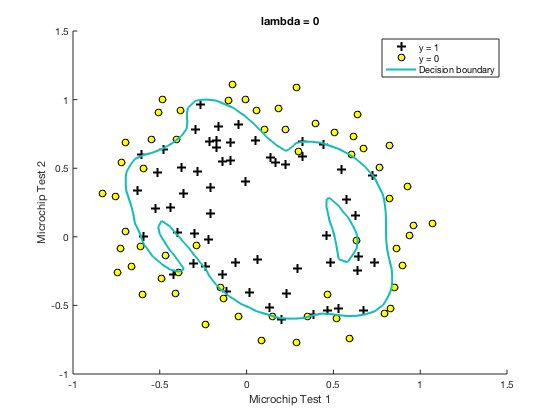

% Plot Boundary
plotDecisionBoundary(theta, X, y);
hold on;
title(sprintf('lambda = %g', lambda))

% Labels and Legend
xlabel('Microchip Test 1')
ylabel('Microchip Test 2')

legend('y = 1', 'y = 0', 'Decision boundary')
hold off;


% Compute accuracy on our training set
p = predict(theta, X);

fprintf('Train Accuracy: %f\n', mean(double(p == y)) * 100);

Train Accuracy: 88.983051


*You do not need to submit any solutions for these optional (ungraded) exercises.*

## Submission and Grading

After completing various parts of the assignment, be sure to use the `submit` function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

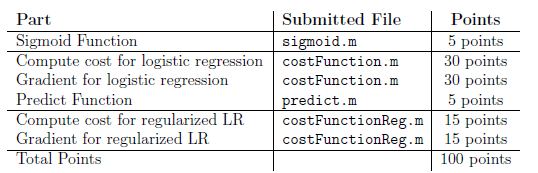

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.